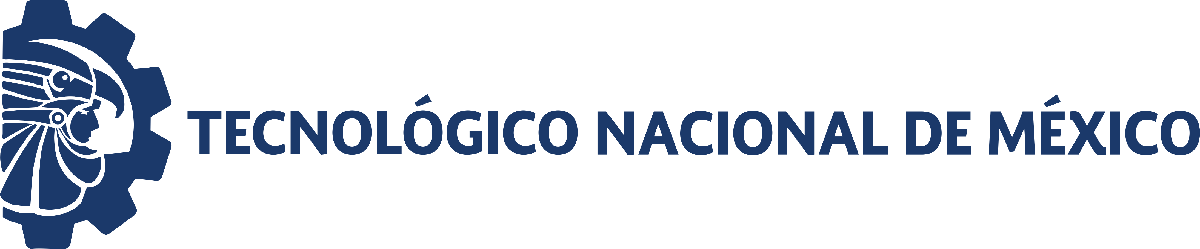                                 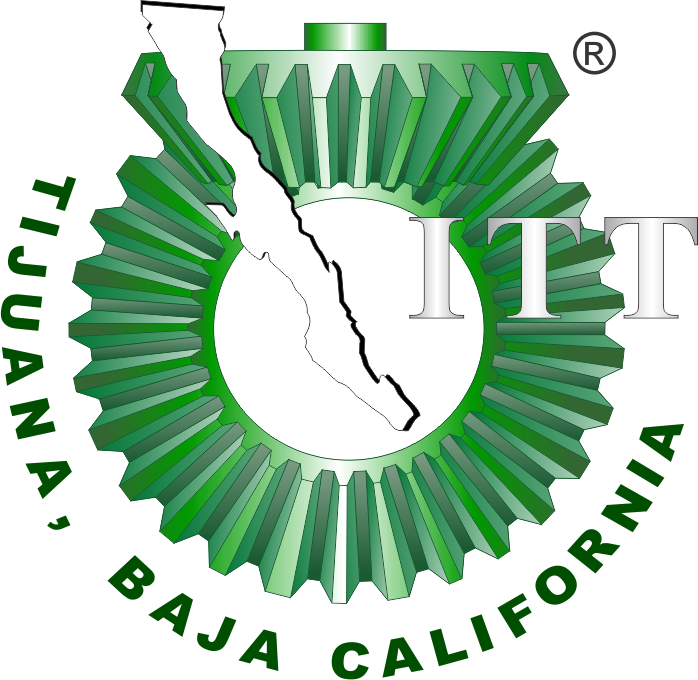

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

***[Figura representativa del sistema elaborada en BioRender] ***

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

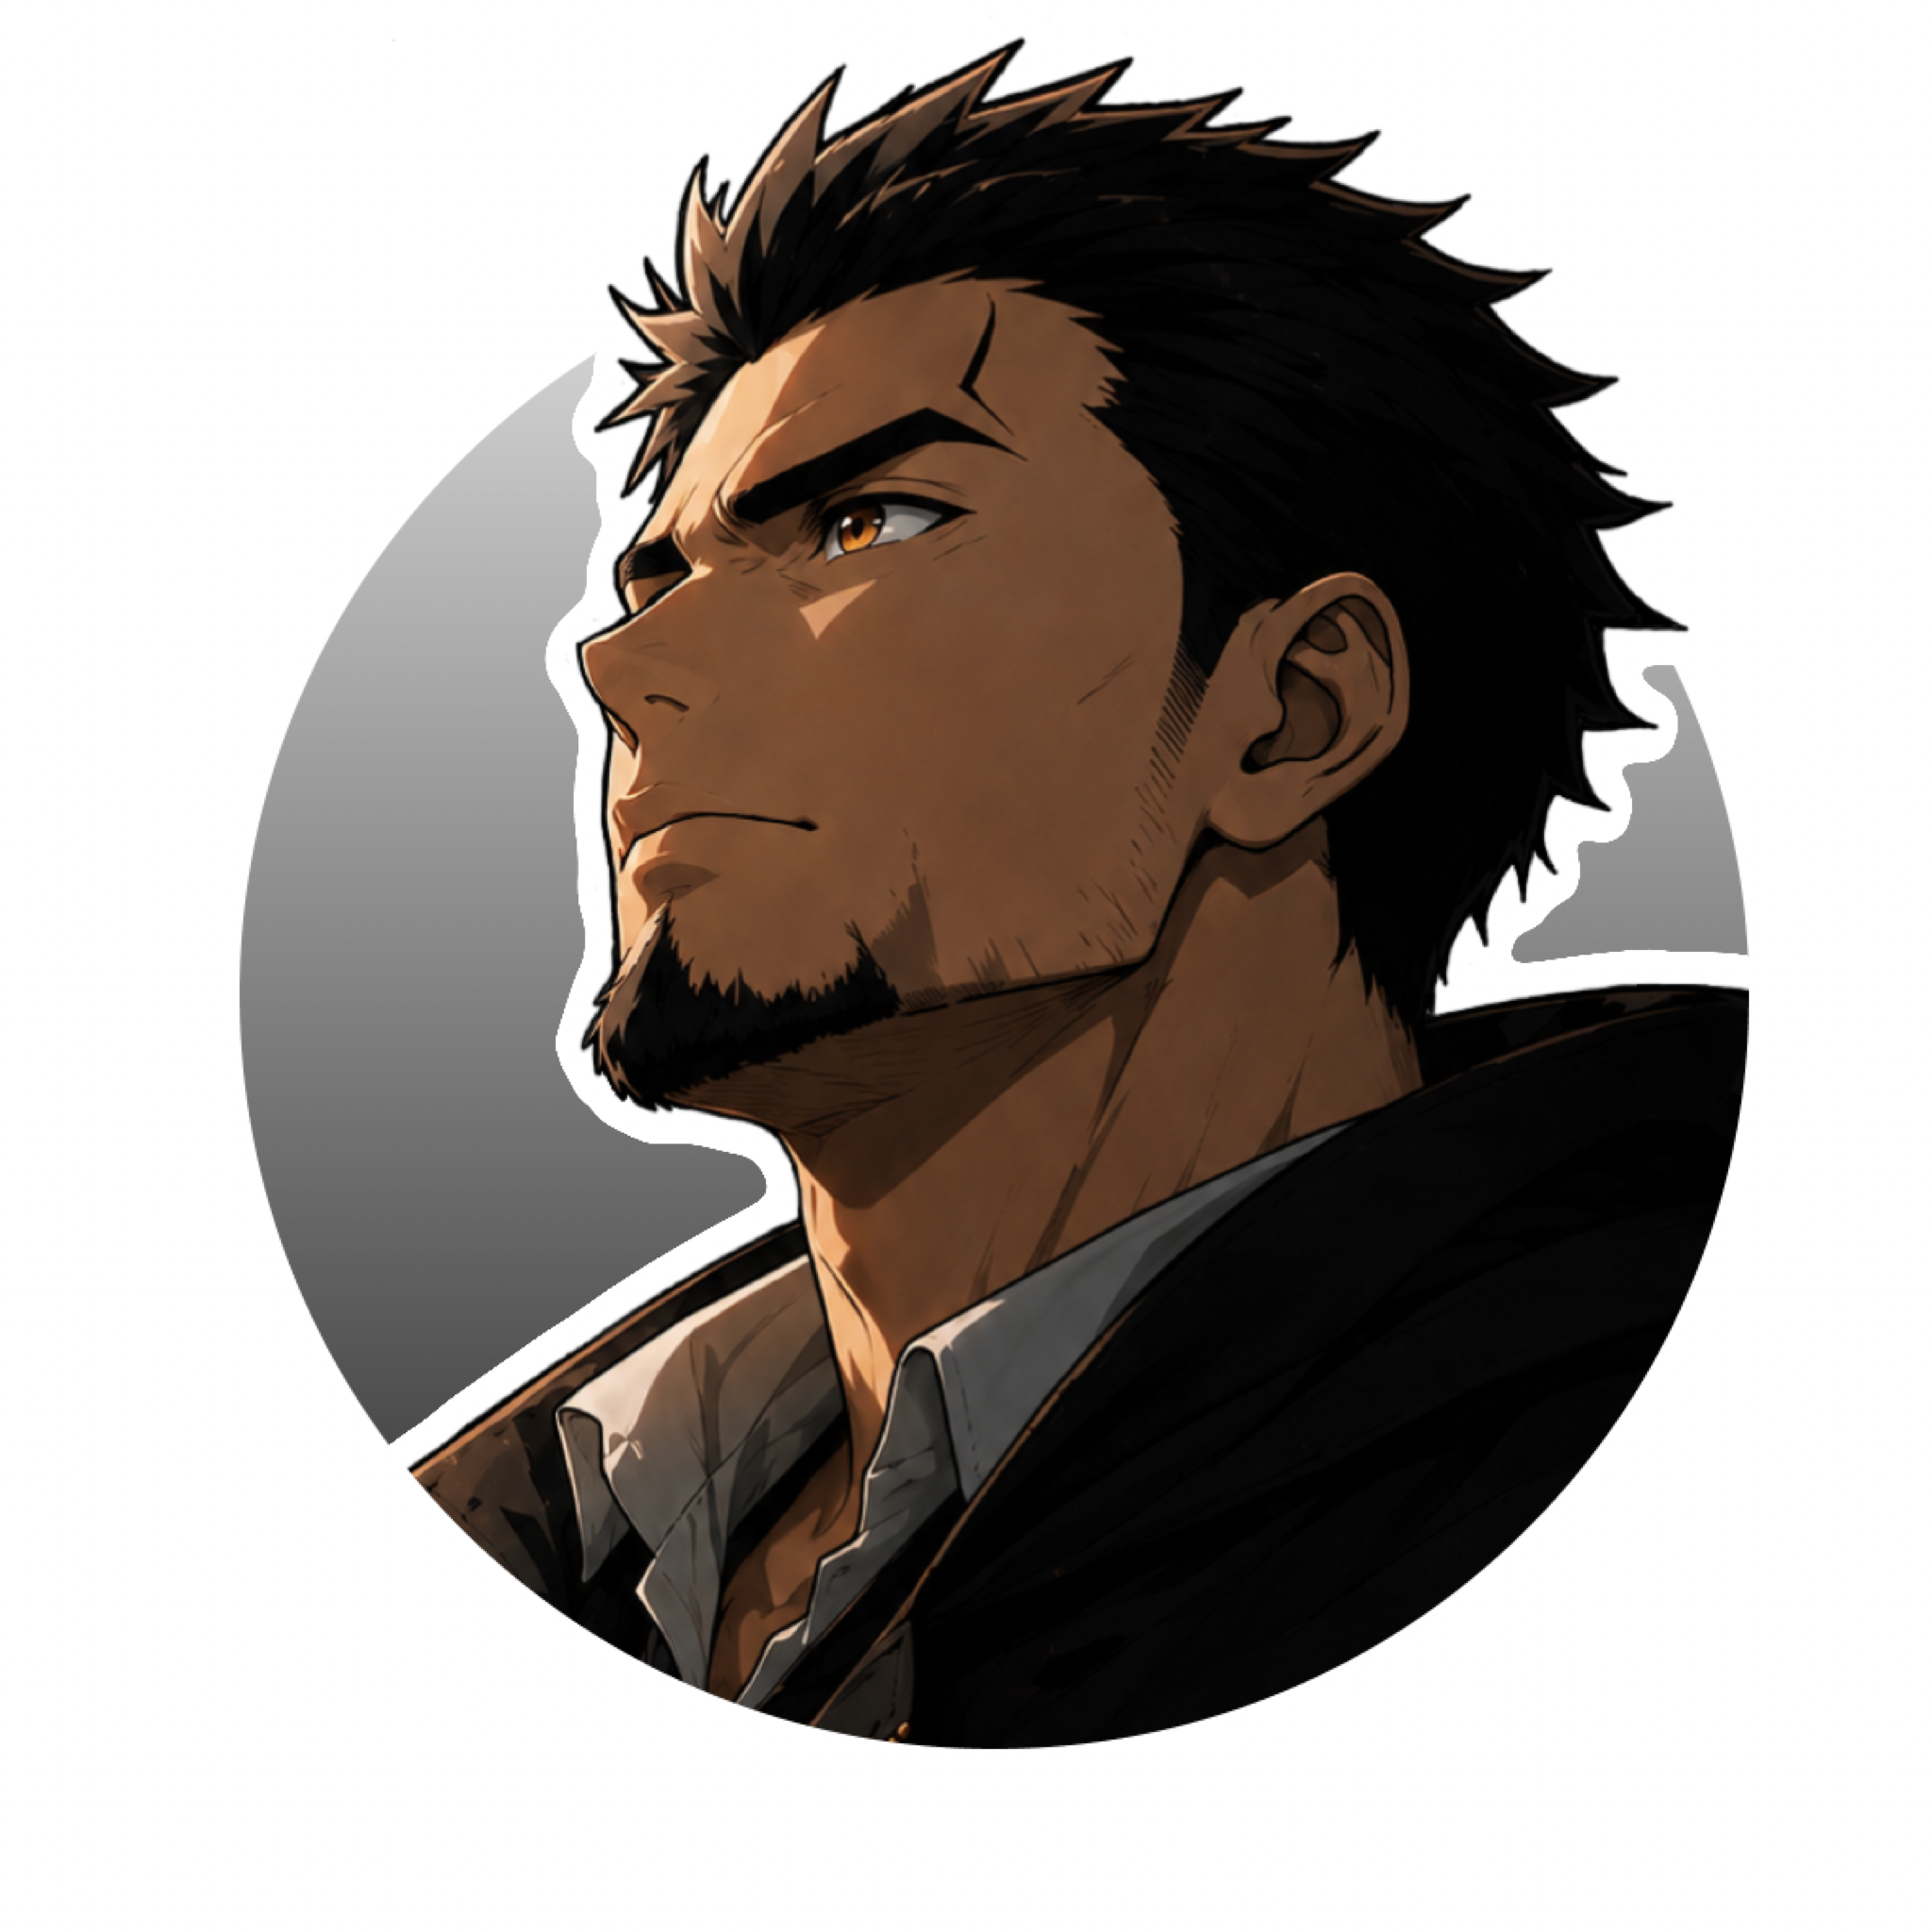

***[Foto 250x250]***

Nombre del alumno: **Flores Gonzalez Emmanuel Alejandro**

Número de control: **M26210085**

Correo institucional: **M26210085@tectijuana.edu.mx**

Asignatura: **Modelado Matemático**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Datos experimentales y ajuste**

clc; clear; close all; warning('off', 'all')

### Datos crudos

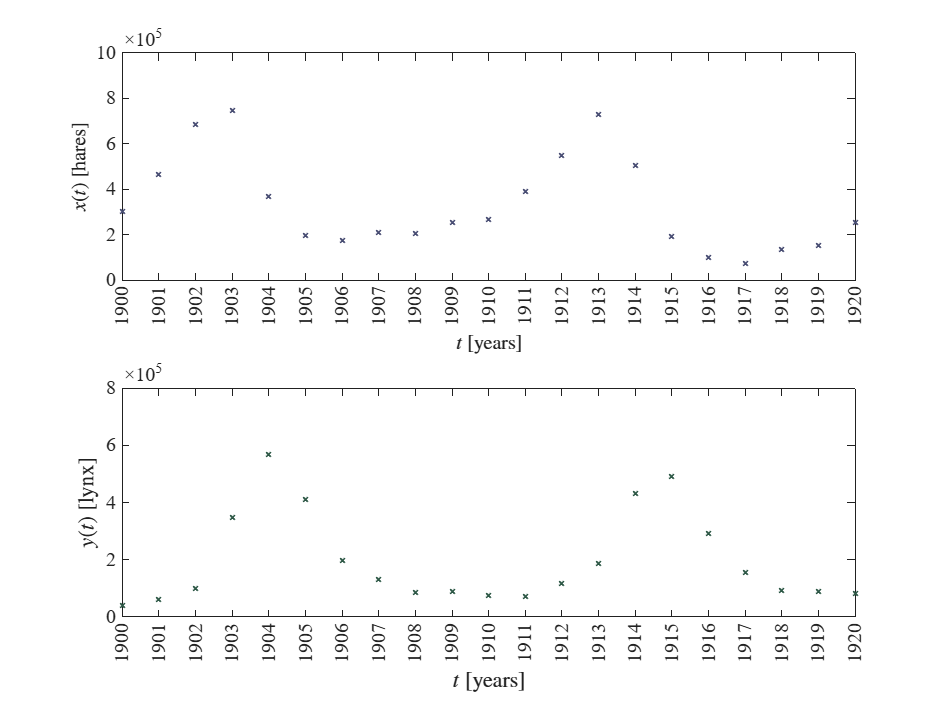

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata (file, smooth, normalize); figname = 'data_raw';
plotsys(t,x,y,figname,normalize)

mdl = fitmodel(t,x,y,[0.5;2/max(y);2/max(x);1], true)


Cantidad de parametros: 4
Grados de libertad: 38
Valor t-student: 0.681
Valor de significancia (alfa) para los intervalos de confianza: 0.500
Relacion n/k<40 para el calculo de AICc: 10.500    Parameters     Estimate         SE           MoE                  CI95                Pvalue  
    __________    __________    __________    __________    ________________________    __________

    {'alpha'}         0.5347      0.021266      0.014482       0.52021       0.54918    2.7517e-25
    {'beta' }     2.8029e-06    1.5565e-07      1.06e-07    2.6969e-06    2.9089e-06    3.3594e-20
    {'delta'}     2.7052e-06    1.1091e-07    7.5527e-08    2.6297e-06    2.7807e-06    8.1581e-25
    {'gamma'}        0.84962      0.035827      0.024398       0.82522       0.87401     2.232e-24


----Crite

mdl = Nonlinear regression model:
    y ~ fitmodel/model(b,X)

Estimated Coefficients:
           Estimate         SE        tStat       pValue  
          __________    __________    ______    __________

    b1        0.5347      0.021266    25.143    2.7517e-25
    b2    2.8029e-06    1.5565e-07    18.007    3.3594e-20
    b3    2.7052e-06    1.1091e-07    24.392    8.1581e-25
    b4       0.84962      0.035827    23.714     2.232e-24


Number of observations: 42, Error degrees of freedom: 38
Root Mean Squared Error: 4.01e+04
R-Squared: 0.961,  Adjusted R-Squared 0.958
F-statistic vs. zero model: 688, p-value = 7.05e-35

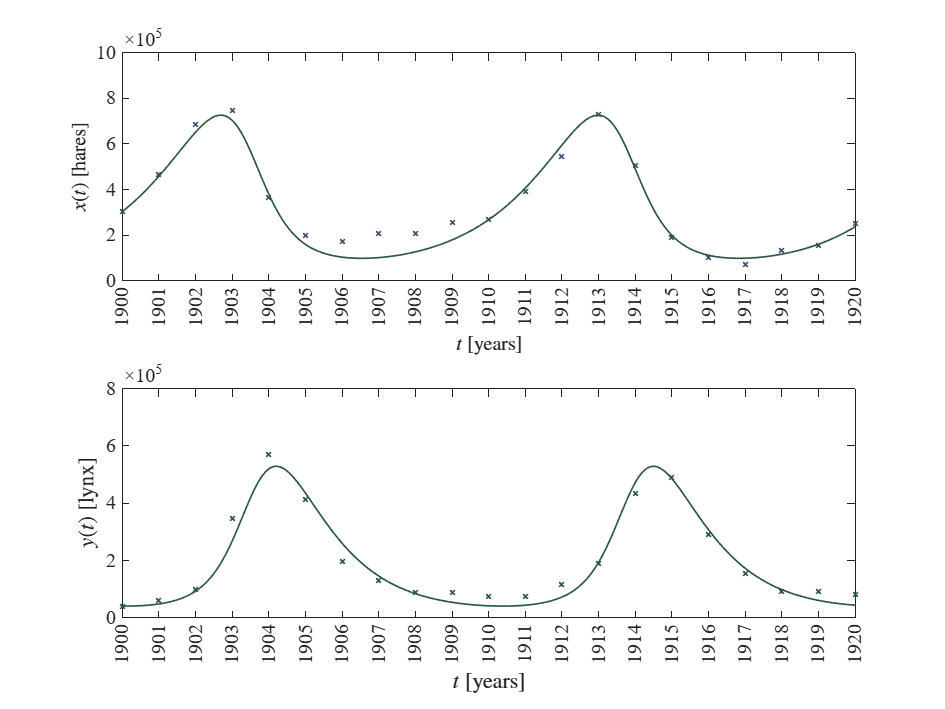

par = table2array(mdl.Coefficients(:,1));
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
save('parameters.mat','alpha','beta','delta','gamma');
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_raw_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

### Datos suavizados

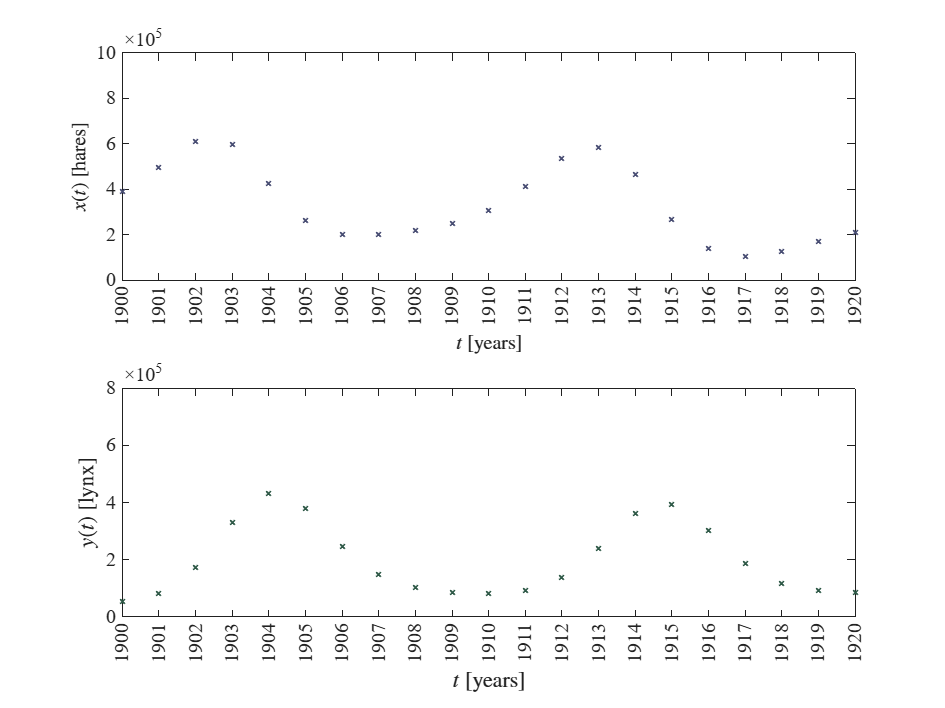

file = 'data.csv'; smooth = true; normalize = false;
[t,x,y] = getdata (file, smooth, normalize); figname = 'data_smooth';
plotsys(t,x,y,figname,normalize)

mdl = fitmodel(t,x,y,[0.5,1/max(y),2/max(x),1], true)


Cantidad de parametros: 4
Grados de libertad: 38
Valor t-student: 0.681
Valor de significancia (alfa) para los intervalos de confianza: 0.500
Relacion n/k<40 para el calculo de AICc: 10.500    Parameters     Estimate         SE           MoE                  CI95                Pvalue  
    __________    __________    __________    __________    ________________________    __________

    {'alpha'}         0.4004      0.020697      0.014095       0.38631        0.4145    2.8638e-21
    {'beta' }     2.2297e-06    1.4205e-07    9.6734e-08     2.133e-06    2.3265e-06    3.3872e-18
    {'delta'}     2.9212e-06    1.4336e-07    9.7629e-08    2.8236e-06    3.0188e-06    4.7143e-22
    {'gamma'}        0.99067      0.050962      0.034705       0.95596        1.0254    2.4219e-21


----Crite

mdl = Nonlinear regression model:
    y ~ fitmodel/model(b,X)

Estimated Coefficients:
           Estimate         SE        tStat       pValue  
          __________    __________    ______    __________

    b1        0.4004      0.020697    19.346    2.8638e-21
    b2    2.2297e-06    1.4205e-07    15.697    3.3872e-18
    b3    2.9212e-06    1.4336e-07    20.377    4.7143e-22
    b4       0.99067      0.050962    19.439    2.4219e-21


Number of observations: 42, Error degrees of freedom: 38
Root Mean Squared Error: 3.33e+04
R-Squared: 0.96,  Adjusted R-Squared 0.956
F-statistic vs. zero model: 887, p-value = 5.96e-37

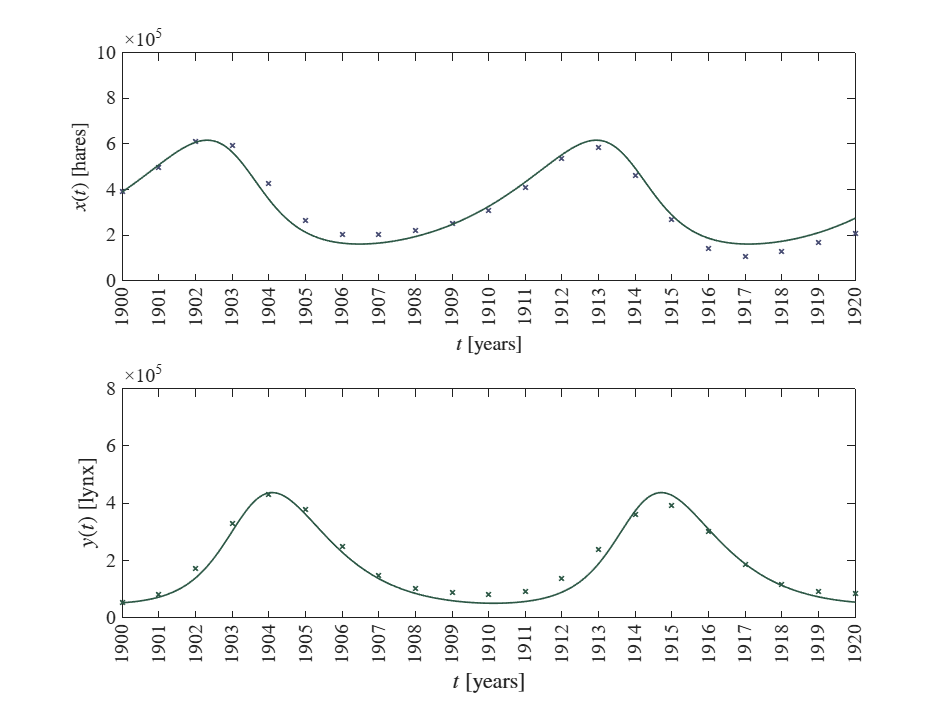

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_smooth_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

### Datos Normalizados

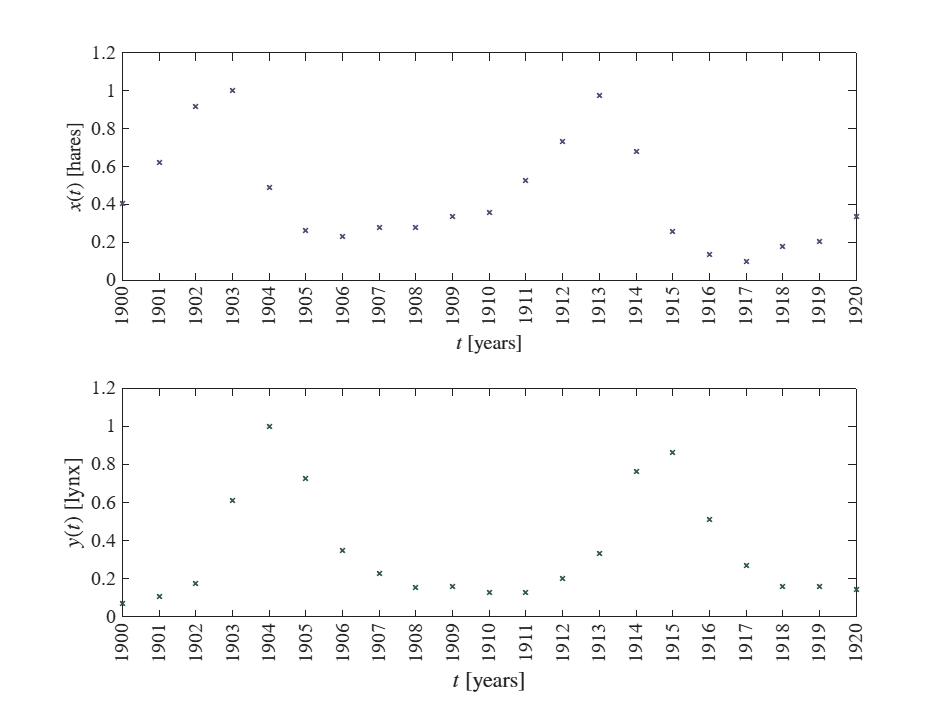

file = 'data.csv'; smooth = false; normalize = true;
[t,x,y] = getdata (file, smooth, normalize); figname = 'data_norm';
plotsys(t,x,y,figname,normalize)

mdl = fitmodel(t,x,y,[1;1;1;1], true)


Cantidad de parametros: 4
Grados de libertad: 38
Valor t-student: 0.681
Valor de significancia (alfa) para los intervalos de confianza: 0.500
Relacion n/k<40 para el calculo de AICc: 10.500    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'alpha'}     0.54272     0.023219    0.015812    0.52691    0.55853    3.7322e-24
    {'beta' }      1.6174     0.087675    0.059707     1.5577     1.6771    1.4704e-20
    {'delta'}       2.012     0.088449    0.060234     1.9518     2.0723    9.7981e-24
    {'gamma'}     0.83423     0.036844    0.025091    0.80914    0.85932     1.156e-23


----Criterios de bondad de ajuste----
Cuadrada ajustada: 0.954
Suma residual de c

mdl = Nonlinear regression model:
    y ~ fitmodel/model(b,X)

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1    0.54272     0.023219    23.374    3.7322e-24
    b2     1.6174     0.087675    18.448    1.4704e-20
    b3      2.012     0.088449    22.748    9.7981e-24
    b4    0.83423     0.036844    22.642     1.156e-23


Number of observations: 42, Error degrees of freedom: 38
Root Mean Squared Error: 0.0602
R-Squared: 0.957,  Adjusted R-Squared 0.954
F-statistic vs. zero model: 662, p-value = 1.43e-34

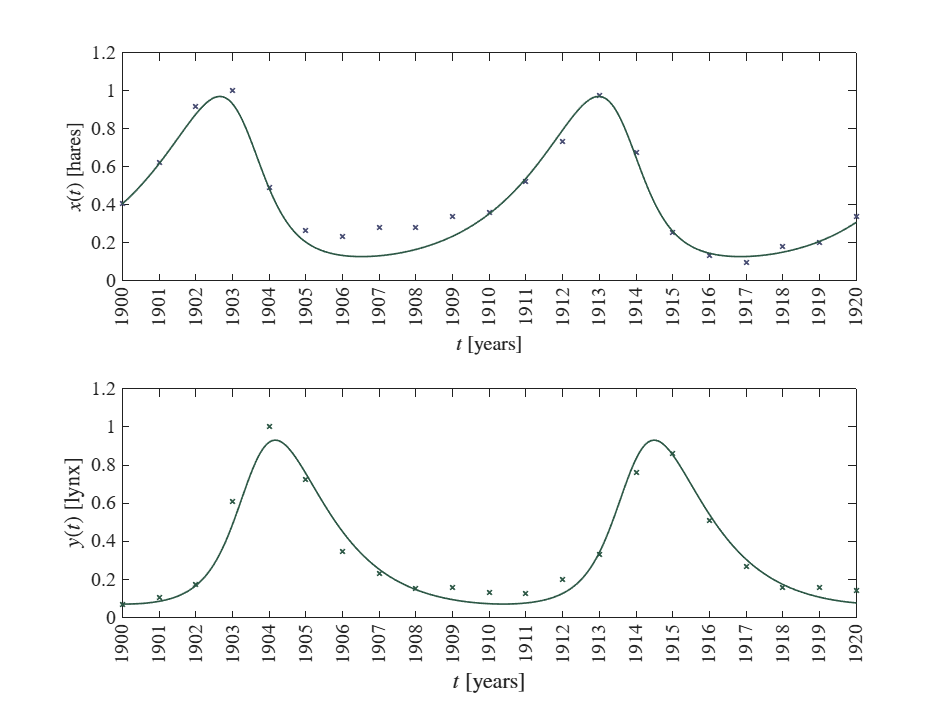

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_norm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

#### Desnormalizacion de los parametros 

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata (file, smooth, normalize);
par(2) = par(2)/max(y);
par(3) = par(3)/max(x);
fprintf('alpha: %.3e, beta: %.3e, delta: %.3e, gamma: %.3e',par(1), par(2),par(3), par(4))

alpha: 5.427e-01, beta: 2.845e-06, delta: 2.689e-06, gamma: 8.342e-01

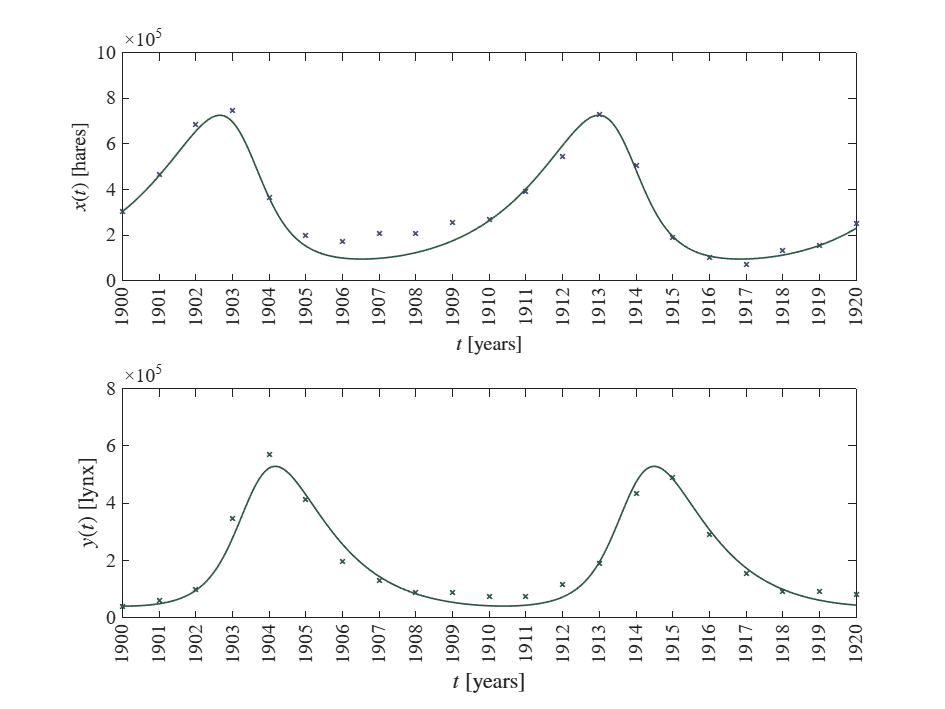

[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_norm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

### Datos suavizados y normalizados

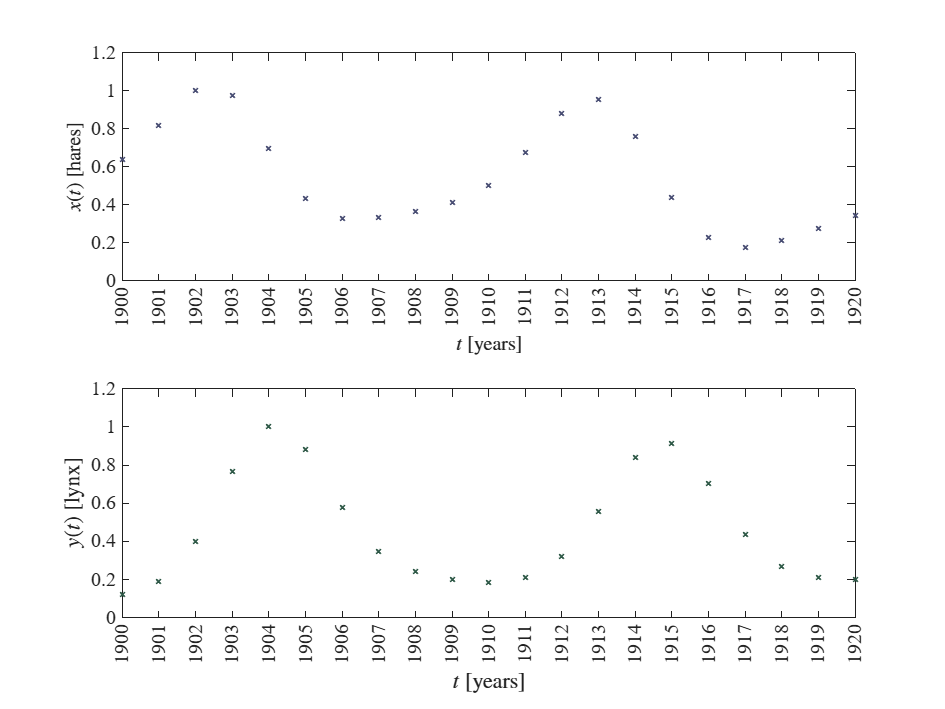

file = 'data.csv'; smooth = true; normalize = true;
[t,x,y] = getdata (file, smooth, normalize); figname = 'data_smoothnorm';
plotsys(t,x,y,figname,normalize)

mdl = fitmodel(t,x,y,[1;1;1;1], true)


Cantidad de parametros: 4
Grados de libertad: 38
Valor t-student: 0.681
Valor de significancia (alfa) para los intervalos de confianza: 0.500
Relacion n/k<40 para el calculo de AICc: 10.500    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'alpha'}     0.40205     0.023059    0.015703    0.38634    0.41775    1.0063e-19
    {'beta' }       0.963     0.062165    0.042334    0.92066     1.0053     5.239e-18
    {'delta'}      1.7814      0.09619    0.065505     1.7159      1.847    1.2859e-20
    {'gamma'}     0.99088     0.055837    0.038025    0.95285     1.0289    5.5299e-20


----Criterios de bondad de ajuste----
Cuadrada ajustada: 0.949
Suma residual de c

mdl = Nonlinear regression model:
    y ~ fitmodel/model(b,X)

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1    0.40205     0.023059    17.436    1.0063e-19
    b2      0.963     0.062165    15.491     5.239e-18
    b3     1.7814      0.09619     18.52    1.2859e-20
    b4    0.99088     0.055837    17.746    5.5299e-20


Number of observations: 42, Error degrees of freedom: 38
Root Mean Squared Error: 0.0627
R-Squared: 0.953,  Adjusted R-Squared 0.949
F-statistic vs. zero model: 863, p-value = 1.01e-36

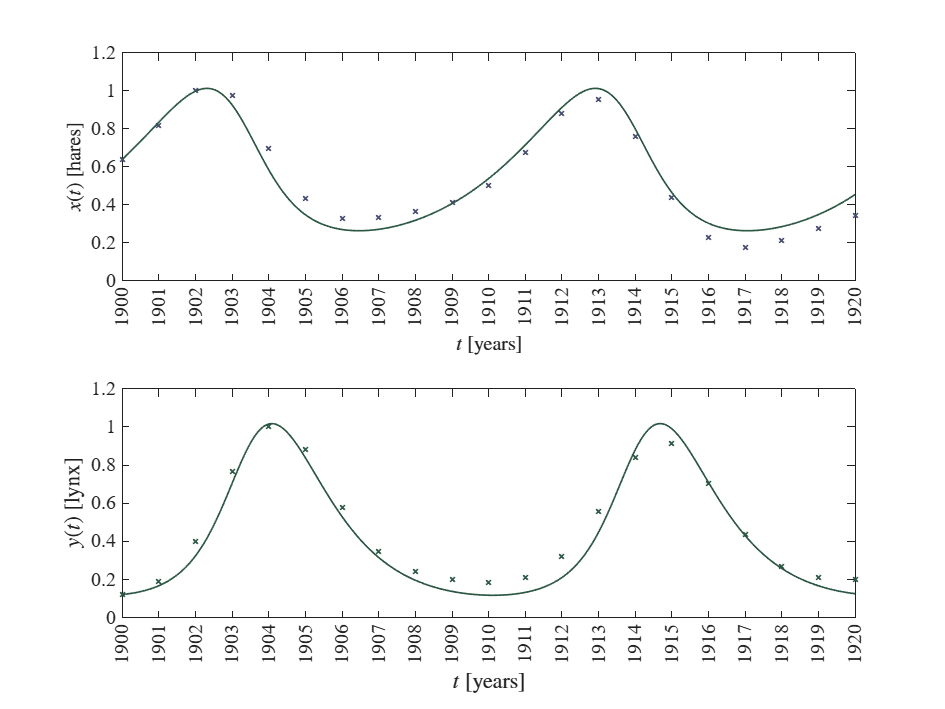

par = table2array(mdl.Coefficients(:,1));
[ta,xa,ya] = LotkaVolterra(par,t,x(1),y(1));
figname = 'data_smoothnorm_fit';
plotfitting(t,x,y,ta,xa,ya,figname,normalize)

## Soluciones y plano de fase

clc; clear; close all; warning('off', 'all')
load ('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata (file, smooth, normalize);
tend =50;
[ta,xa,ya] = LotkaVolterra([alpha,beta,delta,gamma],tend,x(1),y(1));
figname = 'phase_plane';
plotphase(ta,xa,ya,figname)

## Modelo de EDOs con Simulink

clc; clear; close all; warning('off', 'all')
load ('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata (file, smooth, normalize);
x0 = x(1); y0 = y(1);
filesim = 'untitled';
sim(filesim)
parameters.StopTime = '40';
%parameters.MaxStep = '0.1'; 
set_param('untitled/alpha','value',num2str(alpha))
set_param('untitled/beta','value',num2str(beta))
set_param('untitled/delta','value',num2str(delta))
set_param('untitled/gamma','value',num2str(gamma))
set_param('untitled/x0','value',num2str(x0))
set_param('untitled/y0','value',num2str(y0))

## Funcion de ode para ecuaciones stiff

## Funcion ode15s

parameters.Solver = 'ode15s';
f = sim(filesim,parameters);
figname = 'simulink_ode15s';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode23s

parameters.Solver = 'ode23s';
f = sim(filesim,parameters);
figname = 'simulink_ode23s';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode23t

parameters.Solver = 'ode23t';
f = sim(filesim,parameters);
figname = 'simulink_ode15s';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode23tb

parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode15s';
plotphase(f.t,f.x,f.y,figname)

## Funciones ode para ecuaciones nonstiff

% parameters.FixedStep = '1E-1';

## Funcion ode45

parameters.Solver = 'ode45';
f = sim(filesim,parameters);
figname = 'simulink_ode45';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode23

parameters.Solver = 'ode23';
f = sim(filesim,parameters);
figname = 'simulink_ode23';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode113

parameters.Solver = 'ode113';
f = sim(filesim,parameters);
figname = 'simulink_ode113';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode con paso de integracion fijo [diferencias finitas]

parameters.FixedStep = '1E-1';

## Funcion ode1

parameters.Solver = 'ode1';
f = sim(filesim,parameters);
figname = 'simulink_ode1';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode2

parameters.Solver = 'ode2';
f = sim(filesim,parameters);
figname = 'simulink_ode2';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode3

parameters.Solver = 'ode3';
f = sim(filesim,parameters);
figname = 'simulink_ode3';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode4

parameters.Solver = 'ode4';
f = sim(filesim,parameters);
figname = 'simulink_ode4';
plotphase(f.t,f.x,f.y,figname)

## Funcion ode5

parameters.Solver = 'ode5';
f = sim(filesim,parameters);
figname = 'simulink_ode5';
plotphase(f.t,f.x,f.y,figname)

## FUNCION ODE SELECCIONADA: ODE23tb

parameters.MaxStep = '0.1'; 
parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode23tb_dt';
plotphase(f.t,f.x,f.y,figname)

## Funcion anonimas

clc; clear; close all; warning('off', 'all')
load ('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~,x,y] = getdata (file, smooth, normalize);
x0 = x(1); y0 = y(1);
par = [alpha,beta,delta,gamma];

## Funcion ode78

[t,fsol] = ode78(@(t,V)sysODE(V,par),[0,40],[x0,y0]);
x =fsol(:,1);
y =fsol(:,2);
figname = 'function_ode78';
plotphase(t,x,y,figname)

## Funcion ode89

[t,fsol] = ode89(@(t,V)sysODE(V,par),[0,40],[x0,y0]);
x =fsol(:,1);
y =fsol(:,2);
figname = 'function_ode88';
plotphase(t,x,y,figname)

## Funcion con arreglo predefinido del tiempo

tspan = (0:1E-3:40)';
[t,fsol] = ode78(@(t,V)sysODE(V,par),tspan,[x0,y0]);
x =fsol(:,1);
y =fsol(:,2);
figname = 'function_ode89';
plotphase(t,x,y,figname)

## Modelo matematico

function dV = sysODE(V,par) %V(1) = x; V(2) = y
alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
dV = zeros(2,1);
dV(1) = alpha*V(1) - beta*V(1)*V(2);
dV(2) = delta*V(1)*V(2) - gamma*V(2);
end

## Estabilidad de los equilibrios

clc; clear; close all; warning('off', 'all')
load ('parameters.mat')
clr3 = [139,38,38]/255;

% xe0 =0; ye0=0;
% xe1 = gamma/delta; ye1 =alpha/beta;



### Condiciones iniciales:origen

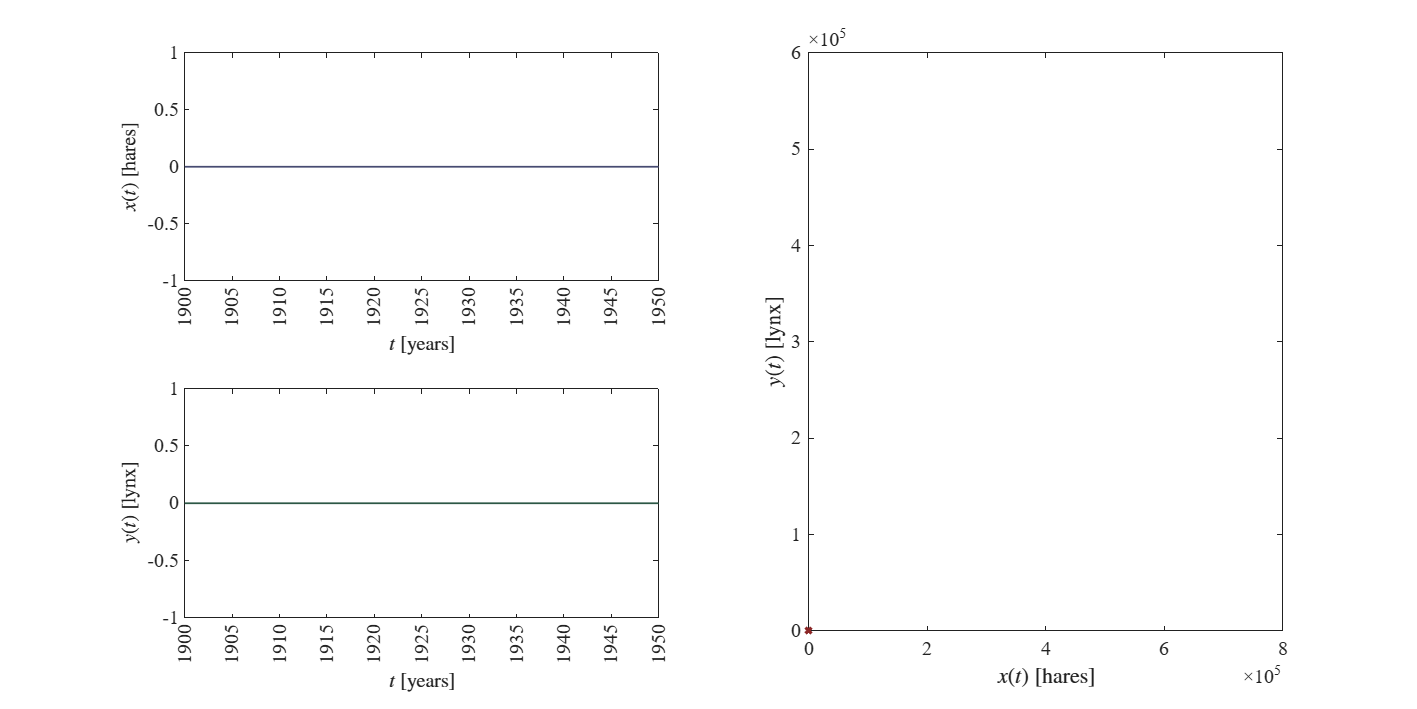

xe0 =0; ye0=0;
tend = 50;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,xe0,ye0);
figname = 'eq_origin';
plotphase(t,x,y,figname);...
    subplot(2,2,1);ylim([-1 1]); yticks(-1:0.5:1);...
    subplot(2,2,3);ylim([-1 1]); yticks(-1:0.5:1);...
    subplot(2,2,[2 4]);plot(xe0,ye0,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)

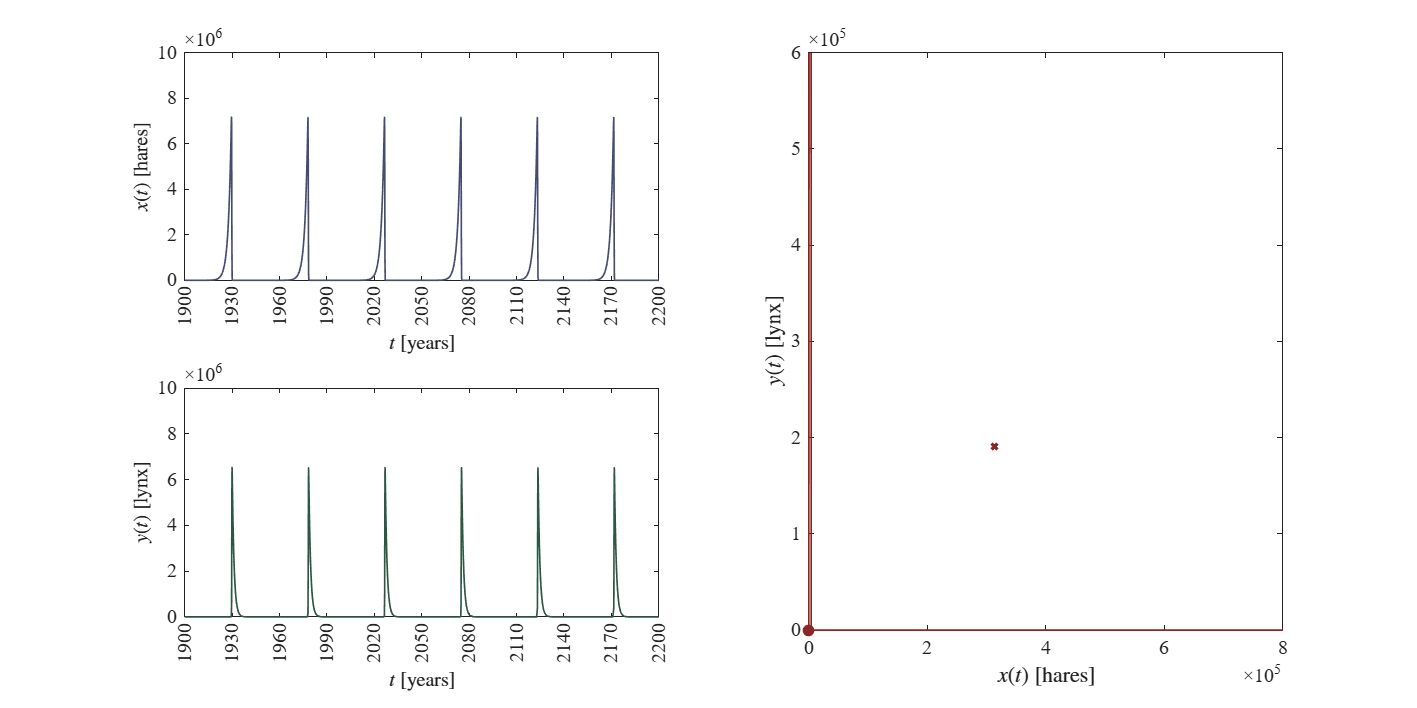

tend = 300;
xe0 =0; ye0=0;
xe1 = gamma/delta; ye1 =alpha/beta;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,1,1);
figname = 'eq_origin_1-1';
plotphase(t,x,y,figname);...
    subplot(2,2,1);ylim([-0 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,3);ylim([-1 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,[2 4]);plot(xe0,ye0,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
    subplot(2,2,[2 4]);plot(xe1,ye1,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
    subplot(2,2,[2 4]);plot(1,1,'O','LineWidth',2,'MarkerSize',5,'Color',clr3)

## Condiciones iniciales equilibrio de especies

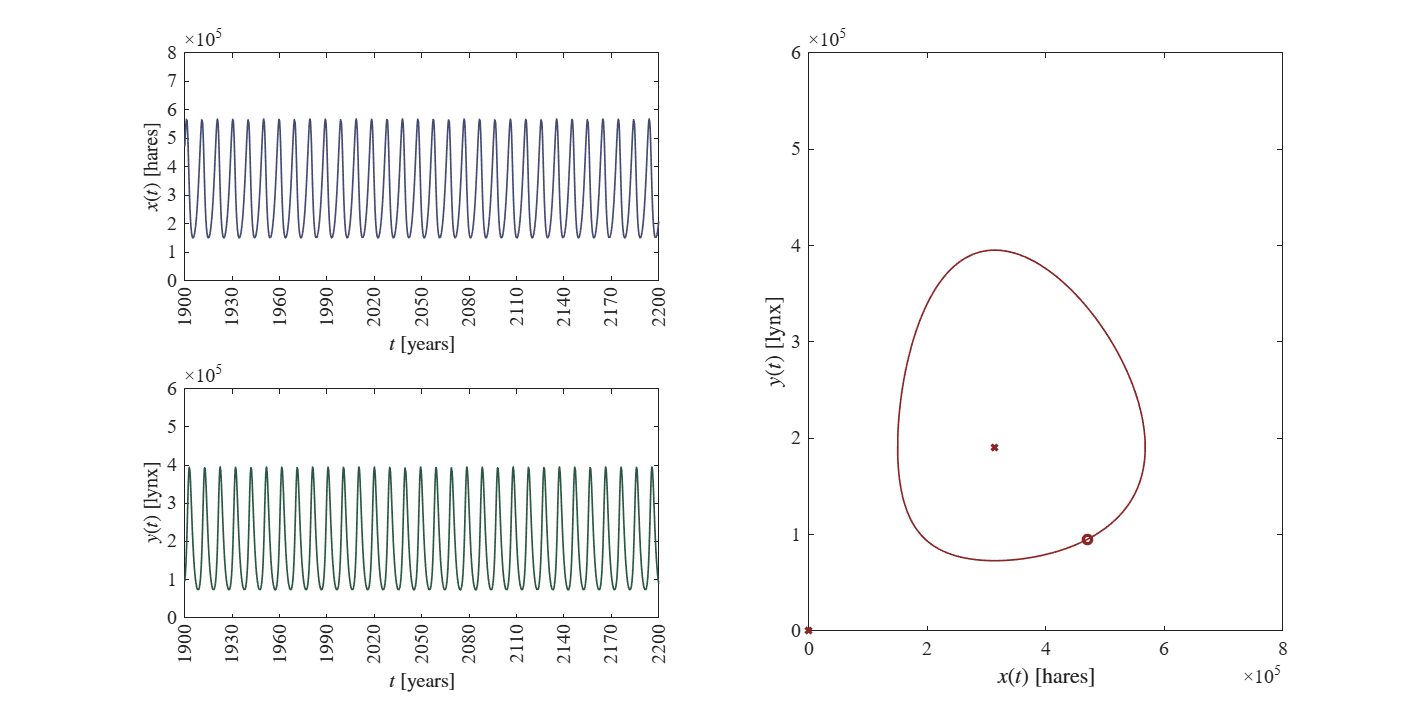

tend = 300;
xe0 =0; ye0=0;
xe1 = gamma/delta; ye1 =alpha/beta;
[t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,1.5*xe1,0.5*ye1);
figname = 'eq_species_1.5xe-0.5ye';
plotphase(t,x,y,figname);...
    subplot(2,2,[2 4]);plot(xe0,ye0,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
    subplot(2,2,[2 4]);plot(xe1,ye1,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
    subplot(2,2,[2 4]);plot(1.5*xe1,0.5*ye1,'O','LineWidth',2,'MarkerSize',5,'Color',clr3)

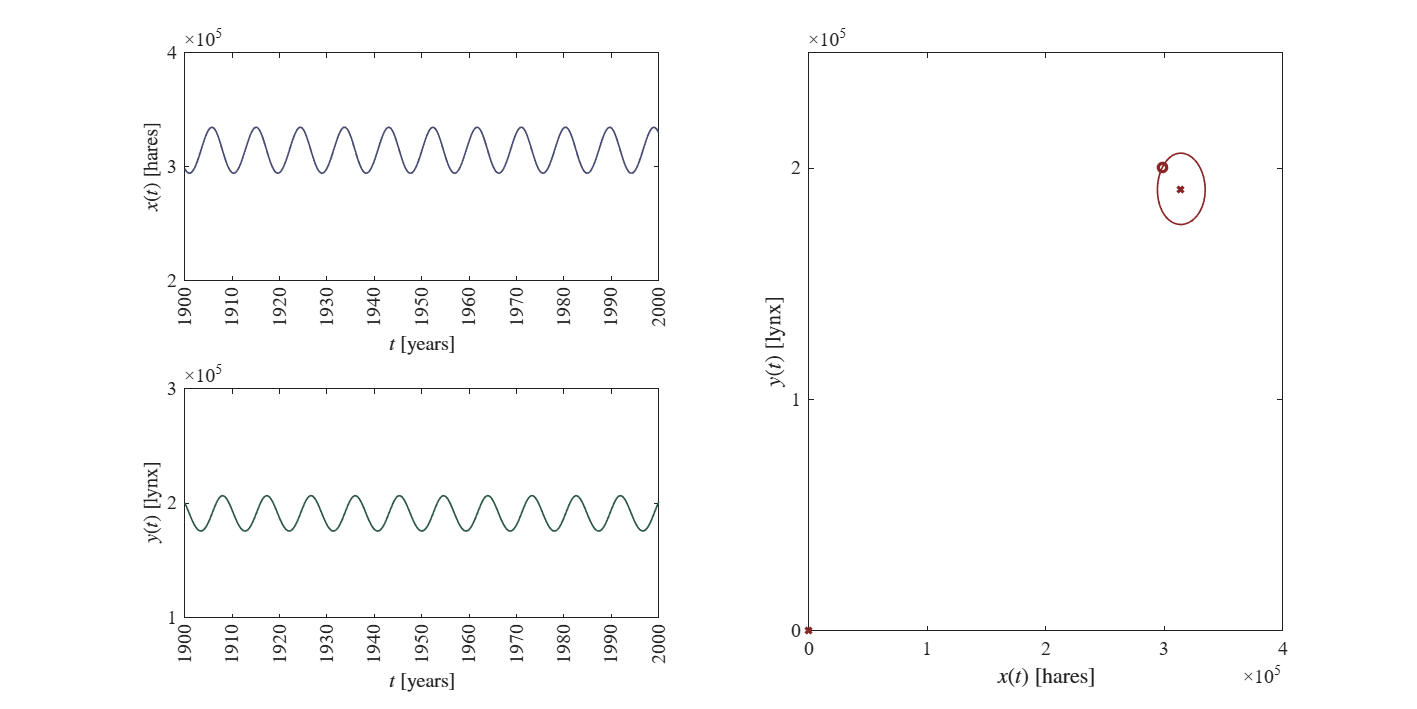

    tend = 100;
    xe0 =0; ye0=0;
    xe1 = gamma/delta; ye1 =alpha/beta;
    [t,x,y] = LotkaVolterra([alpha,beta,delta,gamma],tend,0.95*xe1,1.05*ye1);
    figname = 'eq_species_0.95xe-1.05ye';
    plotphase(t,x,y,figname);...
        subplot(2,2,1);ylim([2E5 4E5]);
        subplot(2,2,3);ylim([1E5 3E5]);
        subplot(2,2,[2 4]);xlim([0 4E5]); ylim([0 2.5E5]);
        subplot(2,2,[2 4]);plot(xe0,ye0,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
        subplot(2,2,[2 4]);plot(xe1,ye1,'x','LineWidth',2,'MarkerSize',5,'Color',clr3)
        subplot(2,2,[2 4]);plot(0.95*xe1,1.05*ye1,'O','LineWidth',2,'MarkerSize',5,'Color',clr3)

##  Funciones

function [to,xo,yo] = getdata (file,smooth,normalize)
    sys = readmatrix (file);
    to = round (sys(:,1));
    to = to - to(1); % t = [0 20] para el ajuste
    xo = sys (:,2)*1E4;
    yo = sys (:,3)*1E4;
        if smooth == false && normalize == false
            return
        elseif smooth == true && normalize == false
            xo = smoothdata(xo,'gaussian',5);
            yo = smoothdata(yo,'gaussian',5);
        elseif smooth == false && normalize == true
            xo = xo / max(xo);
            yo = yo / max(yo);
        elseif smooth == true && normalize == true 
            xo = smoothdata(xo,'gaussian',5);
            yo = smoothdata(yo,'gaussian',5);
            xo = xo / max(xo);
            yo = yo / max(yo);
        end
end

function plotsys(t,x,y,figname,norm)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,15])
    fs = 12; 
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;

    subplot(2,1,1); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'x','linewidth',1,'MarkerSize',4,'color',clr1)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true 
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false 
        ylim([0 10]*1E5); yticks(0:2E5:10E5)
    end

    subplot(2,1,2); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'x','linewidth',1,'MarkerSize',4,'color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
     if norm == true 
        ylim([0 1.2]); yticks(0:0.2:1.2)
     elseif norm == false 
         ylim([0 8]*1E5); yticks(0:2E5:8E5)
     end

    exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end

function mdl = fitmodel(to,xo,yo,p0,biostats)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fa = model(p0,to)
        alpha = p0(1); beta = p0(2);
        delta = p0(3); gamma = p0(4);
        dt = 1e-2; 
        time = (0:dt:max(to))';
        x = zeros(length(time),1); x(1) =x0;
        y = zeros(length(time),1); y(1) = y0;
        n = round(max(to)/dt);

        for i = 1:n %Metodo de Heun (Euler mejorado)
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end
        ta = reshape(to,[],2);
        xa = interp1(time, x, ta(:,1), 'linear');
        ya = interp1(time, y, ta(:,1), 'linear');
        fa = [xa;ya];
    end

    mdl = fitnlm(to,fo,@model,p0);

     if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alfa = 0.5;
        CI95 = coefCI(mdl,alfa);
        dof = mdl.DFE;
        tval = tinv(1-alfa/2,dof);
        MoE = SE * tval;
        Parameters = {'alpha';'beta';'delta';'gamma'};
        R2a = mdl.Rsquared.Adjusted;
        RSS = mdl.SSE;
        AICc = mdl.ModelCriterion.AICc;
        Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
        fprintf('\Cantidad de datos: %.f',numel(fo))
        fprintf('\nCantidad de parametros: %.f',numel(Estimate))
        fprintf('\nGrados de libertad: %.f',dof)
        fprintf('\nValor t-student: %.3f',tval)
        fprintf('\nValor de significancia (alfa) para los intervalos de confianza: %.3f',alfa)
        fprintf('\nRelacion n/k<40 para el calculo de AICc: %.3f',numel(fo)/numel(Estimate))
        disp(Results)
        fprintf('\n----Criterios de bondad de ajuste----')
        fprintf('\nCuadrada ajustada: %.3f',R2a)
        fprintf('\nSuma residual de cuadrados (RSS): %.3f',RSS)
        fprintf('\nCriterio de informacion de Akaike corregido: %.3f', AICc)
     end
end

function plotfitting(t,x,y,ta,xa,ya,figname,norm)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,15])
    fs = 12; 
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;
    
    subplot(2,1,1); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'x','linewidth',1,'MarkerSize',4,'color',clr1)
    plot(ta+1900,xa,'-','linewidth',1,'Color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true 
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false 
        ylim([0 10]*1E5); yticks(0:2E5:10E5)
    end
    
    subplot(2,1,2); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'x','linewidth',1,'MarkerSize',4,'color',clr2)
    plot(ta+1900,ya,'-','linewidth',1,'Color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    if norm == true 
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif norm == false 
        ylim([0 8]*1E5); yticks(0:2E5:8E5)
end

exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end

function [time,x,y] = LotkaVolterra(p0,to,x0,y0)
    alpha = p0(1); beta = p0(2);
    delta = p0(3); gamma = p0(4);
    dt = 1e-2; 
    time = (0:dt:max(to))';
    x = zeros(length(time),1); x(1) =x0;
    y = zeros(length(time),1); y(1) = y0;
    n = round(max(to)/dt);
    
    for i = 1:n %Metodo de Heun (Euler mejorado)
        [fx,fy] = f(x(i),y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn,fyn] = f(xn,yn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end
    
        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end
end

function plotphase(t,x,y,figname)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,30,15])
    fs = 12; 
    clr1 = [70, 75, 113]/255;
    clr2 = [44, 87, 69]/255;
    clr3 = [139, 38, 38]/255;
    
    subplot(2,2,1); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,x,'-','linewidth',1,'color',clr1)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$x(t)$ [hares]','Interpreter','latex')
    xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)
    ylim([0 8]*1E5); yticks(0:1E5:10E5)
    
    subplot(2,2,3); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(t+1900,y,'-','linewidth',1,'color',clr2)
    xlabel('$t$ [years]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)
    ylim([0 6]*1E5); yticks(0:1E5:8E5)

    subplot(2,2,[2 4]); hold on; box on; grid off; 
    fontsize(fs,'points'); set(gca,'fontname','Times new Roman')
    plot(x,y,'-','linewidth',1,'color',clr3)
    xlabel('$x(t)$ [hares]','Interpreter','latex')
    ylabel('$y(t)$ [lynx]','Interpreter','latex')
    xlim([0 8]*1E5); yticks(0:1E5:10E5)
    ylim([0 6]*1E5); yticks(0:1E5:8E5)
    
    exportgraphics(gcf,[figname,'.pdf'],'ContentType','vector')
end